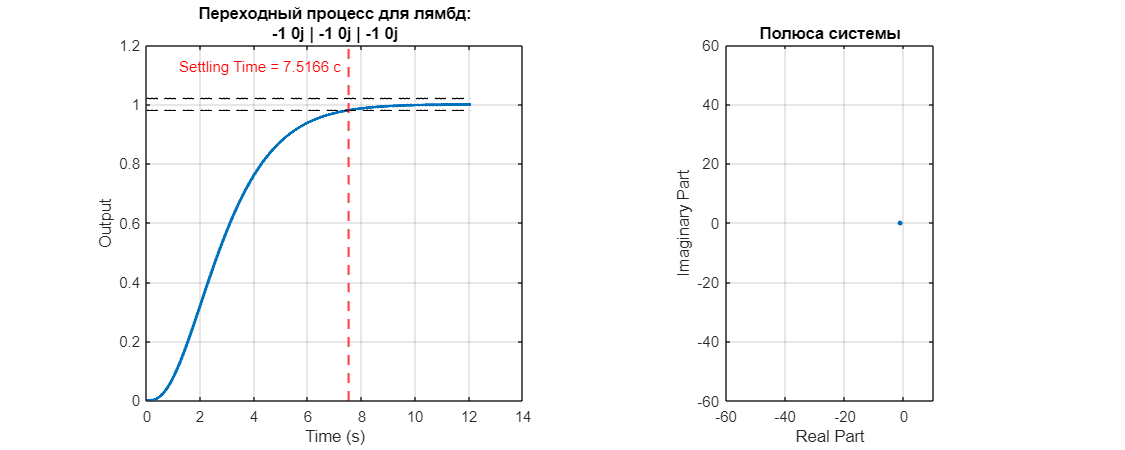

Error using saveas
Invalid or missing path: pic_2/task_2_out_1.png

% Определение набора полюсов
poles = [
    -1, -1, -1;
    -10, -1, -1;
    -30, -1, -1;
    -50, -50, -1;
    -50, -50, -50;
    -1+10i, -1-10i, -1;
    -1+50i, -1-50i, -1;
    -1+10i, -1-10i, -30;
    -1+50i, -1-50i, -30;
    -50+50i, -50-50i, -50
];

% Создание таблицы для хранения результатов
info_table = table('Size', [10, 3], ...
                   'VariableTypes', {'cell', 'double', 'double'}, ...
                   'VariableNames', {'Полюса', 'Время переходного процесса', 'Перерегулирование'});

% Моделирование для всех наборов полюсов
for i = 1:size(poles, 1)
    lambda1 = poles(i, 1);
    lambda2 = poles(i, 2);
    lambda3 = poles(i, 3);
    
    % Построение передаточной функции
    W = tf(abs(lambda1 * lambda2 * lambda3), conv(conv([1, -lambda1], [1, -lambda2]), [1, -lambda3]));
    
    % Переходная характеристика
    [y, t] = step(W);

    % Получение показателей качества
    S = stepinfo(W);

    y_final = y(end);  % Устойчивое значение
    [~, idx_peak] = max(y);  % Индекс пика
    peak = y(idx_peak);  % Значение пика
    
    % Перерегулирование (Overshoot)
    overshoot = (peak - y_final) / y_final;
    
    % Создание фигуры с двумя подграфиками
    figure('Position', [0, 0, 1000, 400]); % Увеличение размера фигуры
    
    % Подграфик 1: Переходная характеристика
    subplot(1, 2, 1);
    plot(t, y, 'LineWidth', 2); hold on;  % Более толстая линия
    lower_limit = y_final * 0.98; % Нижняя граница (98%)
    upper_limit = y_final * 1.02; % Верхняя граница (102%)
    plot(t, ones(size(t)) * lower_limit, 'k--', 'LineWidth', 1); % Нижняя граница 2% зоны
    plot(t, ones(size(t)) * upper_limit, 'k--', 'LineWidth', 1); % Верхняя граница 2% зоны
    xline(S.SettlingTime, 'r--', 'LineWidth', 1.5);
    text(S.SettlingTime, y_final + 0.1, ['Settling Time = ', num2str(S.SettlingTime), ' с  '], 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right', 'Color', 'r');
    hold off;
    grid on;  % Сетка для удобства чтения
    title(sprintf('Переходный процесс для лямбд:\n%d %dj | %d %dj | %d %dj', real(lambda1), imag(lambda1), real(lambda2), imag(lambda2), real(lambda3), imag(lambda3)));
    xlabel('Time (s)');
    ylabel('Output');
    
    % Подграфик 2: Полюса на комплексной плоскости
    subplot(1, 2, 2);
    plot(real([lambda1, lambda2, lambda3]), imag([lambda1, lambda2, lambda3]), '.', 'MarkerSize', 10, 'LineWidth', 2);
    grid on;
    title('Полюса системы');
    xlabel('Real Part');
    ylabel('Imaginary Part');
    axis equal;  % Чтобы оси были одинаковыми по масштабу
    xlim([-60, 10]);  % Ограничиваем область графика для наглядности
    ylim([-60, 60]);

    saveas(gcf, sprintf('pic_2/task_2_out_%d.png', i));
    
    % Запись в таблицу
    info_table{i, 1} = {[lambda1, lambda2, lambda3]};
    info_table{i, 2} = S.SettlingTime;
    info_table{i, 3} = overshoot;
end



% Вывод таблицы с результатами
disp(info_table);